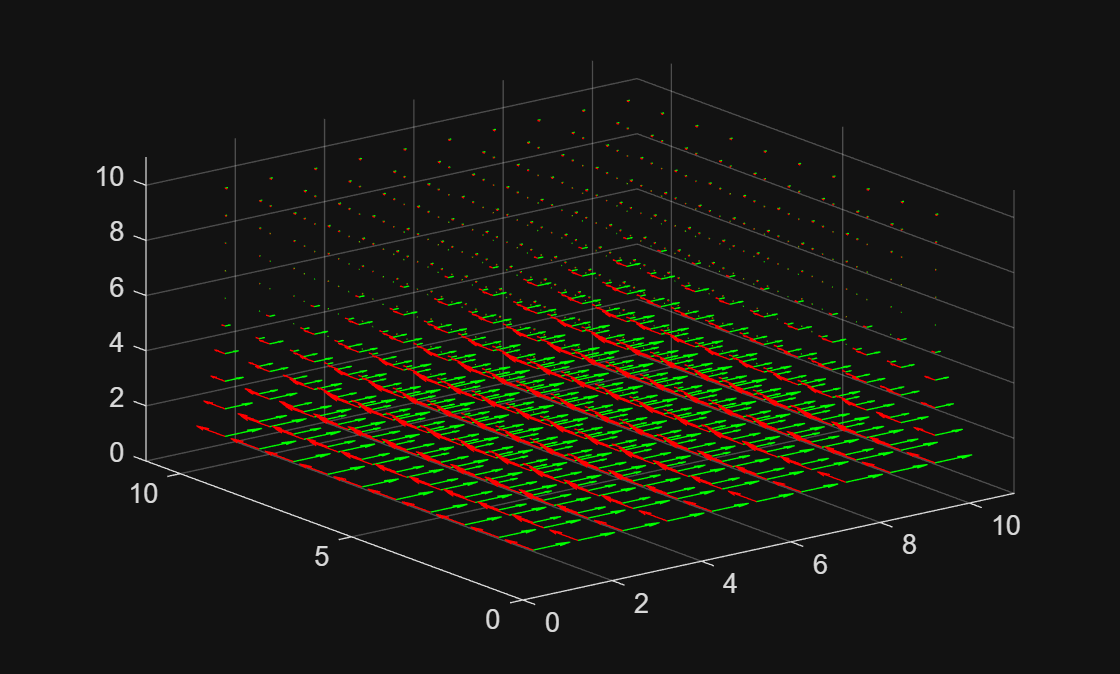

clear all
dt = .3;
c = 1;
omega = 1/50;
dimX = 50;
dimY = 50;
dimZ = 50;
BL_T = 2;

%% boundery test 
% sets boundry to fixed at 0 when true
BCCheck = true;

zeross = zeros(dimX,dimY,dimZ);
E = cat(4,zeross,zeross,zeross);
B = cat(4,zeross,zeross,zeross);
EMag = zeros(100,1);
EMag = zeros(100,1);

n = 10;
dim = 100;

[xn,yn,zn] = meshgrid(1:n, 1:n, 1:n);
[x,y,z] = meshgrid(1:dimX, 1:dimY, 1:dimZ);

BC_L = true([dimX dimY dimZ 3]);
BC_L(BL_T:end-BL_T,BL_T:end-BL_T,BL_T:end-BL_T,:) = false;

for t=1:1000

B(:,:,end/2,1) = cos(2*pi*t*dt*omega);
E(:,:,end/2,2) = cos(2*pi*t*dt*omega);

if BCCheck
E(BC_L) = 0;
B(BC_L) = 0;
end

[C_x,C_y,C_z] = curl(x,y,z,E(:,:,:,1),E(:,:,:,2),E(:,:,:,3));
B = B + dt .* cat(4,C_x,C_y,C_z);

if BCCheck
E(BC_L) = 0;
B(BC_L) = 0;
end

[C_x,C_y,C_z] = curl(x,y,z,B(:,:,:,1),B(:,:,:,2),B(:,:,:,3));
E = E - (dt / c^2) .* cat(4,C_x,C_y,C_z);


P = cross(B,E,4);
P = P(1:(dimX/n):dimX,1:(dimX/n):dimX,1:(dimX/n):dimX,:);
En = E(1:(dimX/n):dimX,1:(dimX/n):dimX,1:(dimX/n):dimX,:);
Bn = B(1:(dimX/n):dimX,1:(dimX/n):dimX,1:(dimX/n):dimX,:);


% quiver3(xn,yn,zn,P(:,:,:,1),P(:,:,:,2),P(:,:,:,3),'w')

quiver3(xn,yn,zn,En(:,:,:,1),En(:,:,:,2),En(:,:,:,3),'r')
ax = gca; % Get the current axes handle
    xlim(ax, [0 11]); % Set x-axis limits
    ylim(ax, [0 11]); % Set y-axis limits
    zlim(ax, [0 11]); % Set z-axis limits
hold on;
quiver3(xn,yn,zn,Bn(:,:,:,1),Bn(:,:,:,2),Bn(:,:,:,3),'g')
% quiver3(xn,yn,zn,P(:,:,:,1),P(:,:,:,2),P(:,:,:,3),'w')
hold off;
drawnow;

EMag(t) = sum(abs(E(:)));
BMag(t) = sum(abs(B(:)));

end


semilogy(1:size(EMag,1),EMag,'r');
hold on;
semilogy(1:size(BMag,2),BMag,'g');
hold off;